# Lab 2

addpath('../LabFiles/Functions/')
addpath('../LabFiles/Images-m/')

## 1  Difference operators

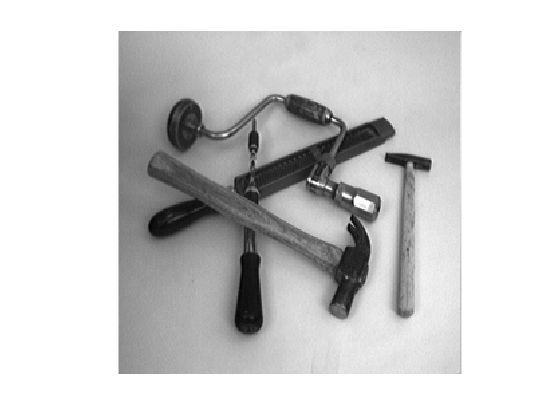

deltax = 0.5*[-1,0,1];
deltay = 0.5*[-1;0;1];

tools = few256;
showgrey(tools);

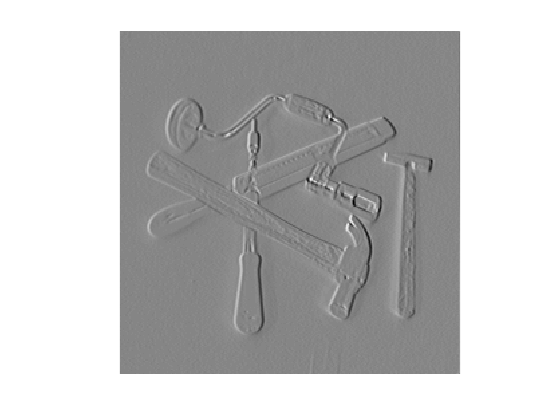

dxtools = conv2(tools, deltax, 'valid');
showgrey(dxtools);

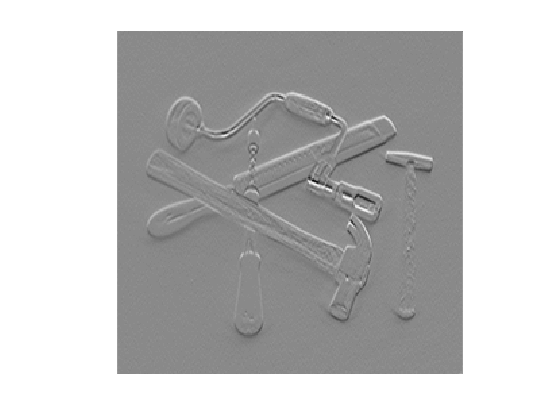

dytools = conv2(tools, deltay, 'valid');
showgrey(dytools)

## 2  Point–wise thresholding of gradient magnitudes

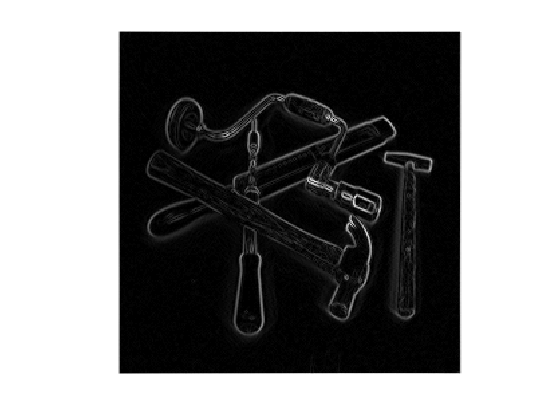

dxtools = conv2(tools, deltax, 'same');
dytools = conv2(tools, deltay, 'same');

gradmagntools = sqrt(dxtools .^2 + dytools .^2);
showgrey(gradmagntools)

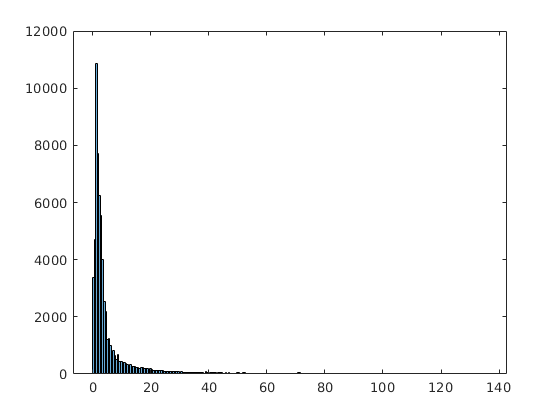

histogram(gradmagntools,256);

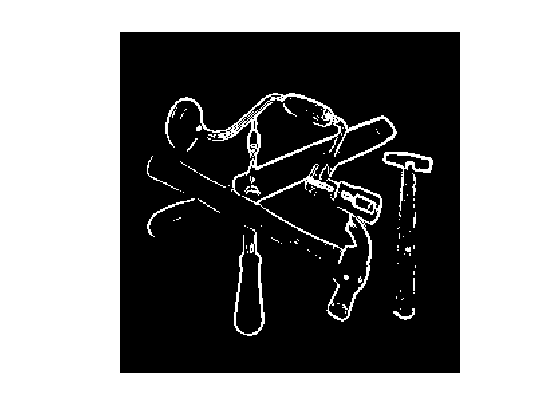


showgrey((gradmagntools - 25) > 0)

img = godthem256;
M = Lv(img)

M = 	1.0e+04 *

    0.3265    0.3050    0.5730    0.8790    1.4164    1.2674    0.9126    0.4920    0.6591    0.6327    0.1981    0.0336    0.0135    0.0913    0.0358    0.0225    0.0583    0.1812    0.1563    0.1940    0.2175    0.2234    0.2148    0.3673    0.5072    0.7716    1.0357    0.9318    0.8590    1.2340    1.4948    1.5376    1.5376    1.5376    1.5376    1.5376    1.5376    1.5376    1.5500    1.5500    1.5500    1.5500    1.5500    1.5500    1.5500    1.5500    1.5625    1.5500    1.5500    1.5500
    0.1371    0.0301    0.3368    0.4435    0.0425    0.3375    0.4285    0.3221    0.2787    0.7569    1.1919    0.1281    0.0276    0.0091    0.0269    0.0400    0.0841    0.0976    0.0372    0.0185    0.0219    0.0165    0.0012    0.0794    0.1366    0.1105    0.0300    0.0335    0.0152    0.1008    0.0281    0.0004    0.0000         0         0         0    0.0000    0.0001    0.0000         0         0    0.0000         0         0         0    0.0000    0.0000    0.0000   

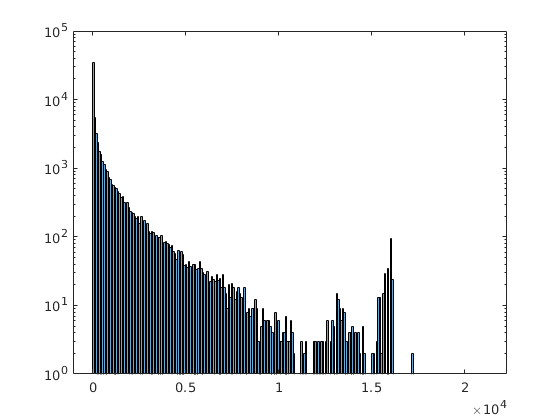



histogram(M,256);
set(gca, 'YScale', 'log')

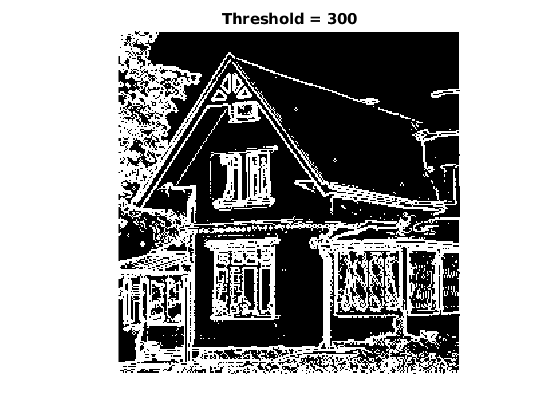

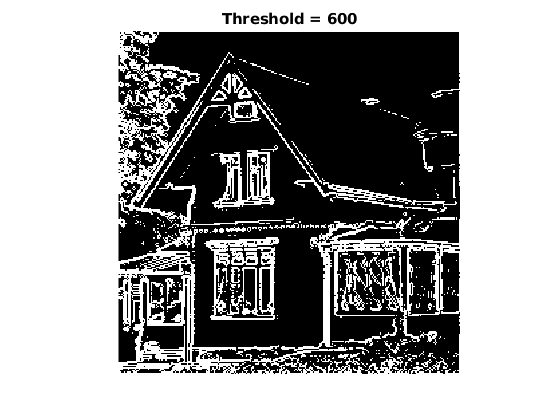

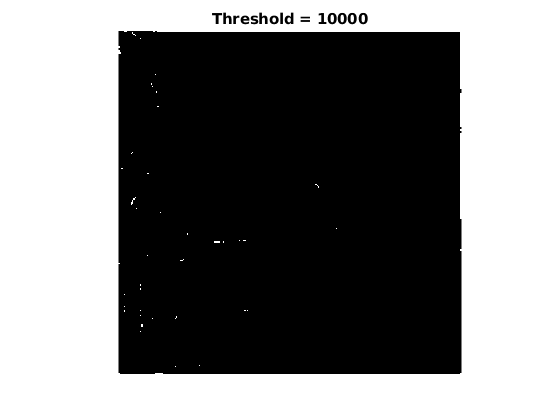


for threshold = [300,600,10000]
    figure();
    showgrey((Lv(img) - threshold) > 0)
    title(sprintf("Threshold = %g",threshold))
end

with smoothing

img = discgaussfft(godthem256,1);
M = Lv(img)

M = 	1.0e+04 *

    0.5248    0.2493    0.4370    0.6939    0.8737    0.8659    0.7606    0.6227    0.5906    0.5154    0.3251    0.1311    0.0604    0.0574    0.0511    0.0357    0.0541    0.1030    0.1460    0.1780    0.2020    0.2255    0.2657    0.3699    0.5232    0.7222    0.9247    0.9809    1.0128    1.1907    1.3570    1.4381    1.4573    1.4526    1.4417    1.4441    1.4551    1.4648    1.4701    1.4571    1.4228    1.4143    1.4263    1.4324    1.4406    1.4469    1.4508    1.4468    1.4410    1.4346
    0.2381    0.0456    0.1374    0.1049    0.0181    0.0473    0.0651    0.0516    0.0606    0.1404    0.2130    0.1053    0.0110    0.0157    0.0344    0.0576    0.0850    0.0988    0.0721    0.0457    0.0320    0.0243    0.0277    0.0572    0.0777    0.0687    0.0255    0.0078    0.0134    0.0311    0.0210    0.0129    0.0152    0.0215    0.0282    0.0276    0.0229    0.0191    0.0195    0.0327    0.0543    0.0586    0.0495    0.0441    0.0383    0.0343    0.0327    0.0346   

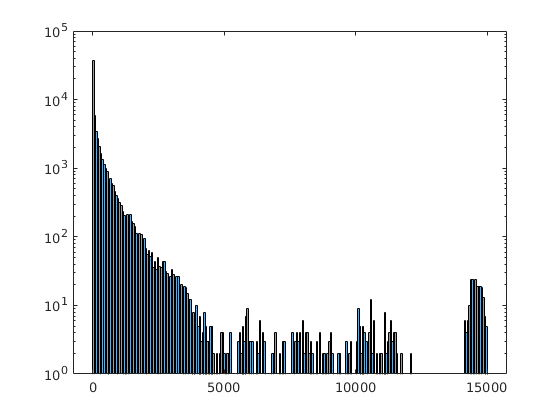



histogram(M,256);
set(gca, 'YScale', 'log')

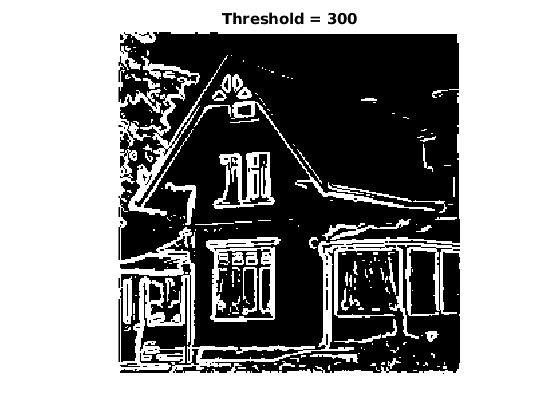

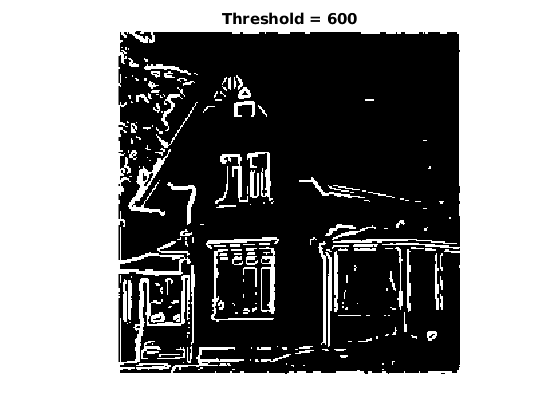

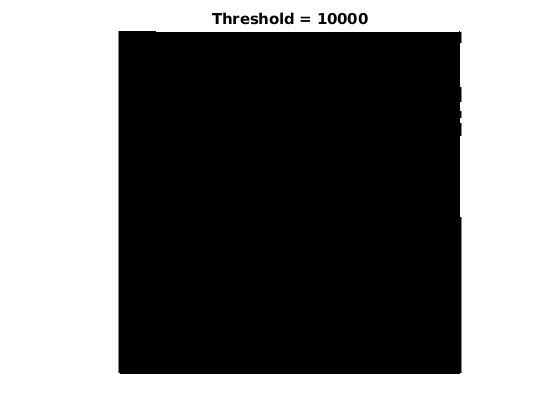


for threshold = [300,600,10000]
    figure();
    showgrey((Lv(img) - threshold) > 0)
    title(sprintf("Threshold = %g",threshold))
end

## 4  Computing differential geometry descriptors

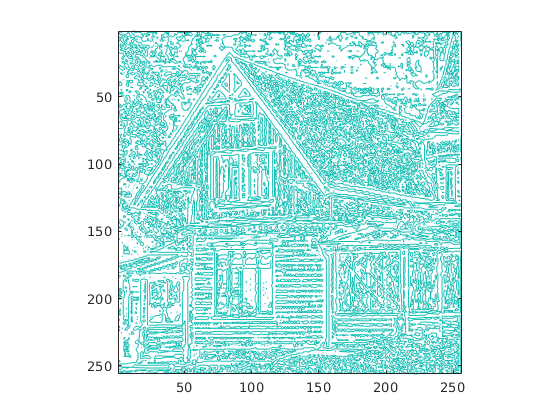

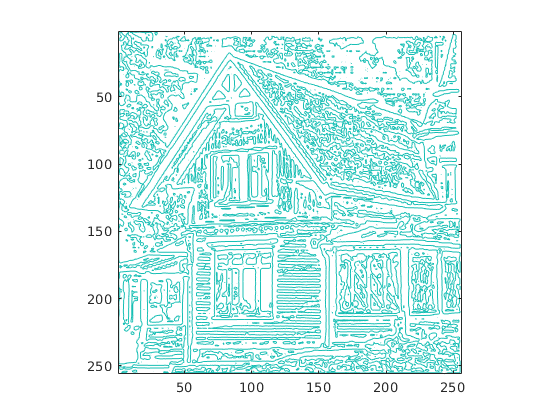

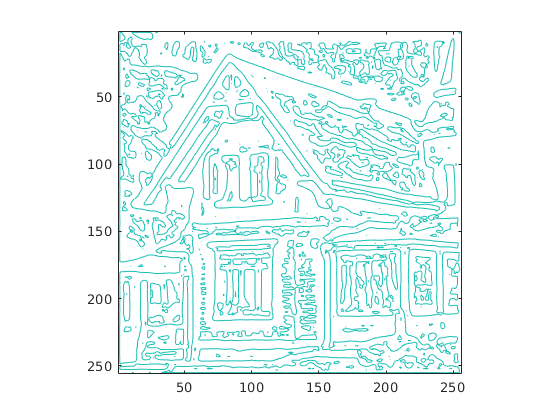

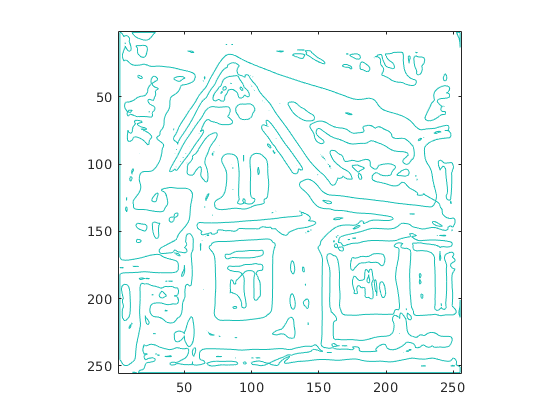

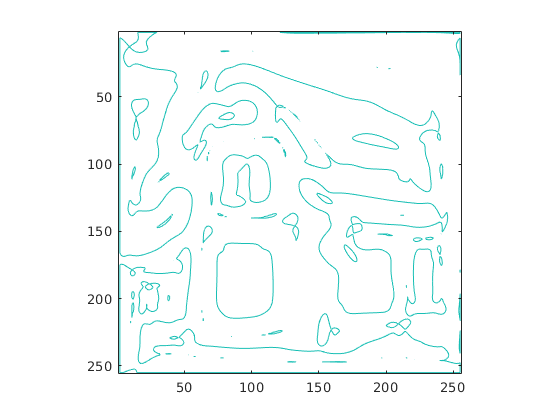

house = godthem256;

for scale = [0.0001 1.0 4.0 16.0 64.0]
    figure();
    contour(Lvvtilde(discgaussfft(house, scale )), [0 0])
    axis('image')
    axis('ij')
end

Now let's see the third derivative

tools = few256;
showgrey(tools)

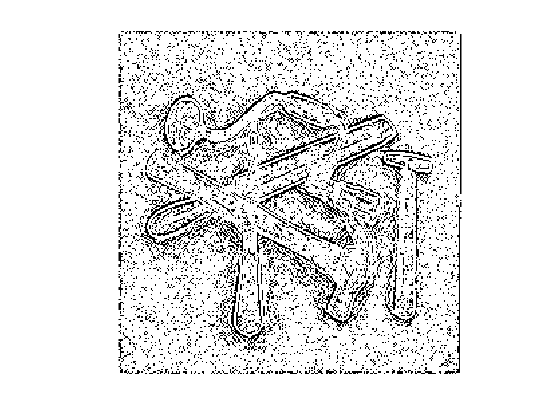

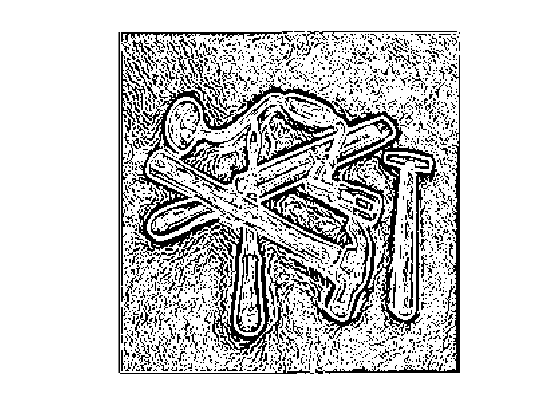

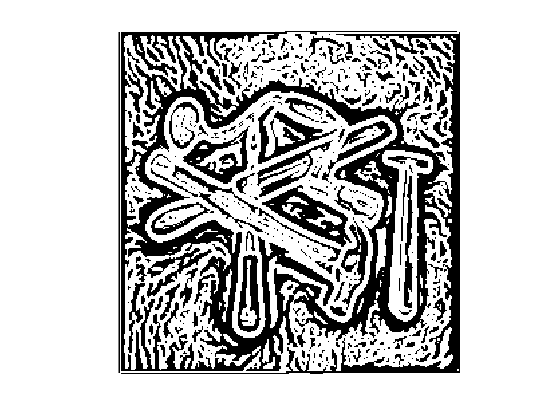

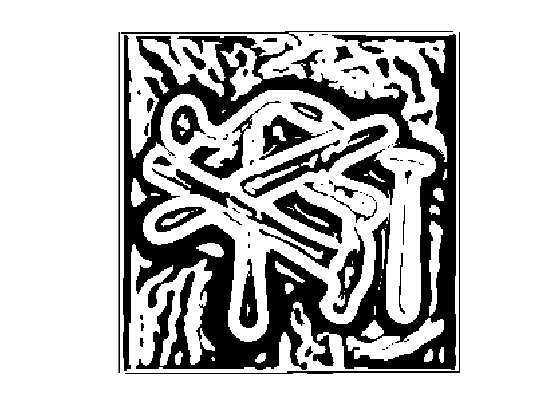

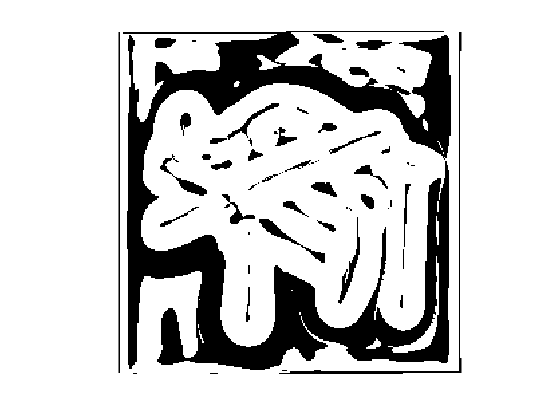

for scale = [0.0001 1.0 4.0 16.0 64.0]
    figure();
    showgrey(Lvvvtilde(discgaussfft(tools, scale)) < 0)
    axis('image')
    axis('ij')
end

## 5  Extraction of edge segments

curves =          0   13.0000   14.0000         0   20.0000   21.0000         0   84.9744   85.0000   86.0000         0   90.0005   90.0001   90.0000   90.0000         0   91.0062   92.0000   92.0010   92.0001         0    2.0000    2.0000         0    2.0000    2.0000         0    2.0000    1.9998         0    2.0000    1.9999         0    2.0000    2.0000         0    2.0000    2.0000         0    2.0000    2.0000    2.0000         0    1.9999    2.0000    2.0000         0    2.0000    2.0000    2.0000
    2.0000  255.0000  255.0000    2.0000  255.0000  255.0000    3.0000  221.0000  221.0400  221.1949    4.0000  184.0000  183.0000  182.0000  181.0000    4.0000  167.0000  166.0021  166.0000  165.0000    2.0000  251.0000  252.0000    2.0000  224.0000  225.0000    2.0000  162.0000  163.0000    2.0000  149.0000  150.0000    2.0000   74.0000   75.0000    2.0000   94.0000   95.0000    3.0000  105.0000  106.0000  107.0000    3.0000  116.0000  117.0000  118.0000    4.0000  122.0000  123.0000

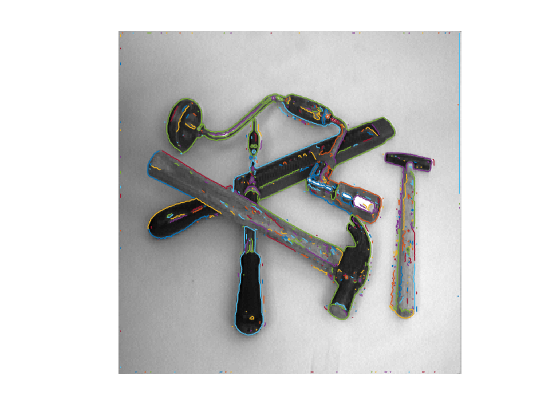

curves =          0    2.0000    3.0000    4.0000    5.0000    6.0000    7.0000    8.0000    9.0000   10.0000   11.0000   12.0000   13.0000   14.0000   15.0000   16.0000   17.0000   18.0000   19.0000   20.0000   21.0000   22.0000   23.0000   24.0000   25.0000   26.0000   27.0000   28.0000   29.0000   30.0000   31.0000   32.0000   33.0000   34.0000   35.0000   36.0000   37.0000   38.0000   39.0000   40.0000   41.0000   42.0000   43.0000   44.0000   45.0000   46.0000   47.0000   48.0000   49.0000   50.0000
  104.0000  255.0002  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000

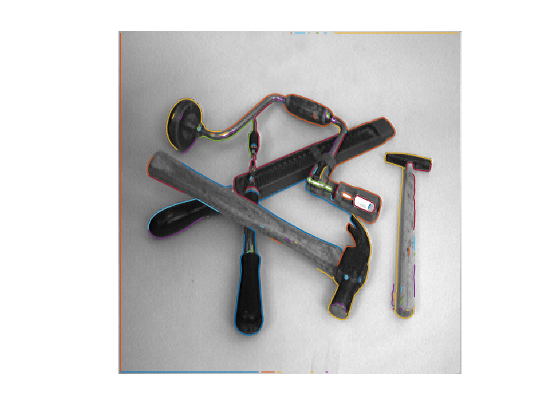

curves =          0    2.0000    3.0000    4.0000    5.0000    6.0000    7.0000    8.0000    9.0000   10.0000   11.0000   12.0000   13.0000   14.0000   15.0000   16.0000   17.0000   18.0000   19.0000   20.0000   21.0000   22.0000   23.0000   24.0000   25.0000   26.0000   27.0000   28.0000   29.0000   30.0000   31.0000   32.0000   33.0000   34.0000   35.0000   36.0000   37.0000   38.0000   39.0000   40.0000   41.0000   42.0000   43.0000   44.0000   45.0000   46.0000   47.0000   48.0000   49.0000   50.0000
  121.0000  255.0002  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000

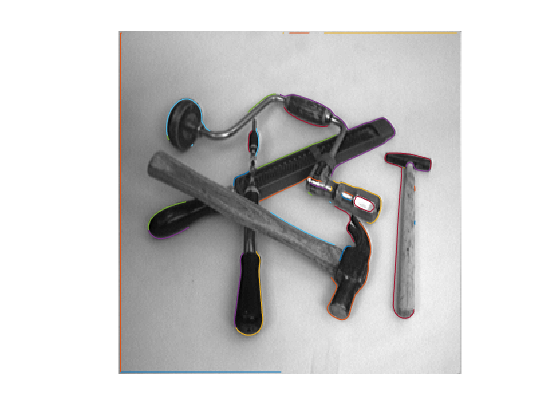

curves =          0    2.0000    3.0000    4.0000    5.0000    6.0000    7.0000    8.0000    9.0000   10.0000   11.0000   12.0000   13.0000   14.0000   15.0000   16.0000   17.0000   18.0000   19.0000   20.0000   21.0000   22.0000   23.0000   24.0000   25.0000   26.0000   27.0000   28.0000   29.0000   30.0000   31.0000   32.0000   33.0000   34.0000   35.0000   36.0000   37.0000   38.0000   39.0000   40.0000   41.0000   42.0000   43.0000   44.0000   45.0000   46.0000   47.0000   48.0000   49.0000   50.0000
  118.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000

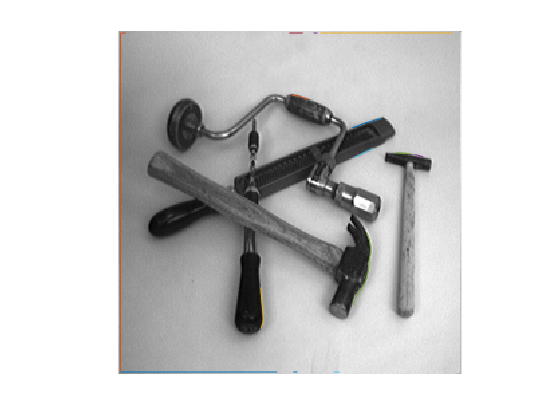

curves =          0    2.0000    3.0000    4.0000    5.0000    6.0000    7.0000    8.0000    9.0000   10.0000   11.0000   12.0000   13.0000   14.0000   15.0000   16.0000   17.0000   18.0000   19.0000   20.0000   21.0000   22.0000   23.0000   24.0000         0   36.0000   37.0000   38.0000   39.0000   40.0000   41.0000   42.0000   43.0000   44.0000   45.0000   46.0000   47.0000   48.0000   49.0000   50.0000   51.0000   52.0000   53.0000   54.0000   55.0000   56.0000   57.0000   58.0000   59.0000   60.0000
   23.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000   45.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000

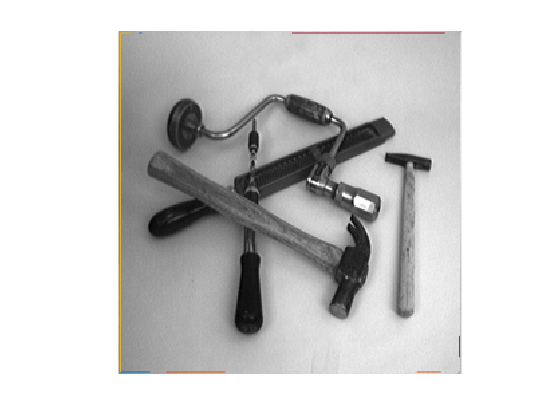

tools = few256;

for scale = [0.0001 1.0 4.0 16.0 64.0]
    figure();
    curves = extractedge(tools,scale, 200, 'same');
    curves
    overlaycurves(tools, curves);

end

## 6  Hough transform